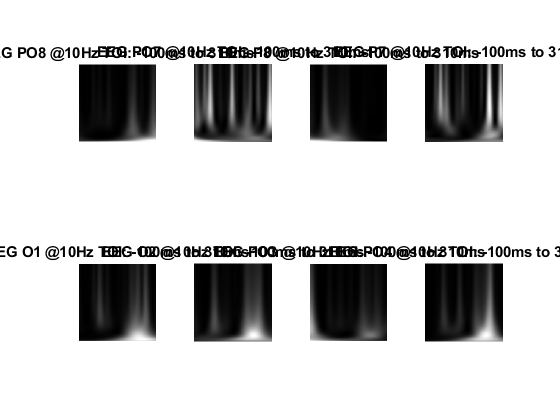

figure
%title('All 8 Channels: EEGPO8,EEGPO7,EEGP8,EEGP7,EEGO1,EEGO2,EEGPO3,EEGPO4. TOI:310ms to 1310ms')
for d = 1:8
I = Imgfig(:,:,d);
J(:,:,d) = imresize (I, [206 206]);
end

subplot(2,4,1),imshow(J(:,:,1));
title('EEG PO8 @10Hz TOI: -100ms to 310ms')
%axis on
%set(gca,'XLim', (-50 310))
%axis manual
subplot(2,4,2),imshow(J(:,:,2));
title('EEG PO7 @10Hz TOI: -100ms to 310ms')
subplot(2,4,3),imshow(J(:,:,3));
title('EEG P8 @10Hz TOI: -100ms to 310ms')
subplot(2,4,4),imshow(J(:,:,4));
title('EEG P7 @10Hz TOI: -100ms to 310ms')
subplot(2,4,5),imshow(J(:,:,5));
title('EEG O1 @10Hz TOI: -100ms to 310ms')
subplot(2,4,6),imshow(J(:,:,6));
title('EEG O2 @10Hz TOI: -100ms to 310ms')
subplot(2,4,7),imshow(J(:,:,7));
title('EEG PO3 @10Hz TOI: -100ms to 310ms')
subplot(2,4,8),imshow(J(:,:,8));
title('EEG PO4 @10Hz TOI: -100ms to 310ms')

cfg = [];
                    cfg.baselinetype = 'absolute';
                    cfg.maskstyle = 'saturation';
                    cfg.zlim         =  'maxmin';
                    %cfg.trial        = trigger_idx(1);
                    %cfg.channel      = 'EEG PO3';
                    
                    [EEG_Spec_Multi] = ft_multiplotTFR(cfg, TFRwavelet);

the call to "ft_selectdata" took 0 seconds


Error using ft_prepare_layout (line 946)
no layout detected, please specify cfg.layout

Error in ft_multiplotTFR (line 336)
cfg.layout = ft_prepare_layout(tmpcfg, data);